% rgb
map=([1 1 0; 1 0 0; 0 1 1; 0.2 0.2 0.2; 1 0 1; 0.8 0.8 0.8])

map =     1.0000    1.0000         0
    1.0000         0         0
         0    1.0000    1.0000
    0.2000    0.2000    0.2000
    1.0000         0    1.0000
    0.8000    0.8000    0.8000


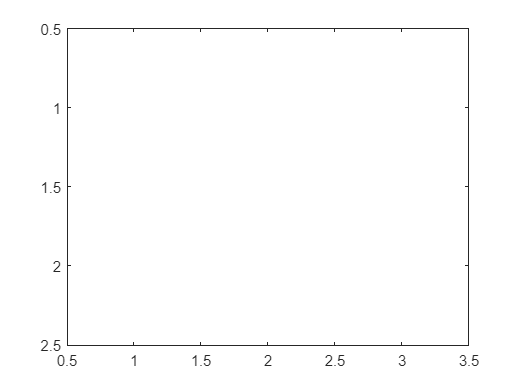

image([1 , 2 , 3; 4, 5, 6])
colormap(map)

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


N(1:3:end, 1)

ans =      1
    10


N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1=[1, 1, 1, 1]

v1 =      1     1     1     1


v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1]

v3 =     0.2500    0.5000         0    0.5000    1.0000


v1 .* v2

ans =     0.5000    0.2500         0    0.2500


s1=sum(v1 .* v2)

s1 = 1

%v1 .* v3
%s2=sum(v1 .* v3);

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


bild = imread('Butterfly.tif');
fargbild = double(bild) / 255;
mygray = (fargbild(:,:,1) + fargbild(:,:,2) + fargbild(:,:,3))/3;
imwrite(mygray, 'mygray.png');

mygrey = imread('mygray.png');
b61 = mygrey(1:2:end, 1:2:end);

b61 = 140×210 uint8 matrix
   46   46   61   58   54   50   51   50   50   59   64   69   68   64   64   62   55   65   60   62   53   55   54   56   54   53   49   47   49   47   47   48   42   43   44   45   45   43   45   43   42   40   44   45   42   44   39   46   39   45
   54   55   58   58   52   59   52   52   55   63   63   65   63   63   66   62   67   58   61   59   60   58   57   53   54   52   51   54   49   49   49   49   47   47   47   47   46   45   43   46   44   43   44   44   45   46   42   48   49   44
   57   67   63   53   53   60   48   51   57   58   60   65   65   63   64   64   61   60   60   57   61   57   59   51   56   50   49   50   47   50   52   48   47   46   45   43   47   48   44   43   44   45   44   44   46   45   43   46   47   46
   55   57   59   52   56   56   53   50   54   50   59   61   63   61   61   59   57   58   57   61   50   53   58   52   53   48   50   50   51   47   46   49   48   47   46   45   44   43   43   43   41   44   43   44

imwrite(b61, 'b61.png');

b63_nearest = imresize(b61, 2, 'nearest');

b63_nearest = 280×420 uint8 matrix
   46   46   46   46   61   61   58   58   54   54   50   50   51   51   50   50   50   50   59   59   64   64   69   69   68   68   64   64   64   64   62   62   55   55   65   65   60   60   62   62   53   53   55   55   54   54   56   56   54   54
   46   46   46   46   61   61   58   58   54   54   50   50   51   51   50   50   50   50   59   59   64   64   69   69   68   68   64   64   64   64   62   62   55   55   65   65   60   60   62   62   53   53   55   55   54   54   56   56   54   54
   54   54   55   55   58   58   58   58   52   52   59   59   52   52   52   52   55   55   63   63   63   63   65   65   63   63   63   63   66   66   62   62   67   67   58   58   61   61   59   59   60   60   58   58   57   57   53   53   54   54
   54   54   55   55   58   58   58   58   52   52   59   59   52   52   52   52   55   55   63   63   63   63   65   65   63   63   63   63   66   66   62   62   67   67   58   58   61   61   59   59   60   60  

b63_linear = imresize(b61, 2,'bilinear');

b63_linear = 280×420 uint8 matrix
   46   46   46   50   57   60   59   57   55   53   51   50   51   51   50   50   50   52   57   60   63   65   68   69   68   67   65   64   64   64   63   60   57   58   63   64   61   61   62   60   55   54   55   55   54   55   56   56   55   54
   48   48   48   51   57   60   59   57   55   54   53   52   51   51   51   51   51   53   58   61   63   65   67   68   67   66   65   64   65   64   63   61   59   59   62   62   61   60   61   60   57   55   56   56   55   55   55   55   54   54
   52   52   53   55   58   59   58   57   54   54   56   56   53   52   52   53   54   56   60   62   63   64   65   66   65   64   63   64   65   65   63   63   64   63   61   60   61   61   60   60   59   58   57   57   56   56   55   54   54   54
   55   56   57   58   59   59   58   56   53   54   57   57   53   51   52   53   55   58   61   62   62   63   64   65   64   64   63   64   65   65   64   64   65   64   61   60   61   61   60   59   60   60   

b63_cubic = imresize(b61, 2,'bicubic');

b63_cubic = 280×420 uint8 matrix
   45   45   44   48   58   62   59   57   55   53   50   49   51   51   50   50   49   52   57   61   63   65   68   69   69   67   65   64   64   64   63   60   55   56   64   66   61   60   62   60   54   52   54   55   54   54   56   56   55   54
   48   48   47   50   58   61   59   57   55   53   52   52   51   51   50   50   50   53   58   61   63   65   67   68   68   66   65   64   64   64   63   61   58   59   63   64   61   60   61   60   55   54   56   56   55   55   55   55   54   54
   52   52   52   53   57   59   59   57   53   53   56   56   53   52   52   52   53   56   61   64   63   64   66   66   65   64   63   64   66   65   63   62   65   64   60   59   61   61   60   60   59   59   57   57   56   56   54   54   54   54
   55   56   57   58   59   59   58   56   52   53   59   59   53   50   51   53   55   58   61   62   62   63   65   65   63   63   63   64   66   66   63   64   67   65   60   58   60   61   58   58   61   61   5


imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic, 'b63_cubic.png');

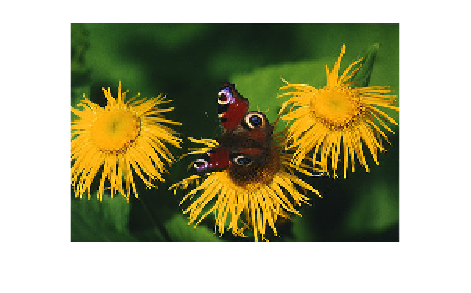

mycolorimage = imread('Butterfly.tif');
b64 = imresize(mycolorimage, 0.5, 'nearest');
b64 = imresize(b64, 2, 'nearest');
imshow(b64)

imwrite(b64, 'b64.png');

%6.5
mycolorR = mycolorimage(:, :, 1)

mycolorR = 280×420 uint8 matrix
   38   44   38   45   53   50   50   45   46   42   42   44   42   39   40   45   42   47   50   51   53   58   59   55   57   55   53   53   53   53   51   50   45   52   55   52   50   52   52   51   44   44   46   46   44   44   46   47   43   42
   48   53   46   48   53   49   50   48   45   45   46   46   43   40   41   43   43   49   52   53   53   56   56   53   54   54   53   53   54   53   51   49   56   56   54   51   49   49   47   44   50   50   49   47   44   42   42   41   41   41
   46   52   47   47   50   47   50   52   46   50   52   49   45   43   44   44   46   50   54   54   52   54   54   53   52   52   52   54   55   54   51   48   57   52   48   49   51   51   49   48   51   51   48   47   47   45   43   42   43   42
   43   50   50   49   50   47   48   52   46   52   54   48   43   42   43   43   47   50   52   53   51   52   54   54   52   52   52   54   55   54   52   50   52   46   45   49   52   51   51   54   50   50   47

mycolorG = mycolorimage(:, :, 2)

mycolorG = 280×420 uint8 matrix
    82    88    82    89    97    94    94    89    91    87    87    88    86    83    84    88    86    91    96    97   102   108   109   106   106   104   102   102   102   102   100    99    91    98   101    98    96    98    98    97    90    90    92    92    90    89    91    92    86    85
    92    97    90    92    97    93    94    92    90    90    91    90    87    84    85    86    87    93    98    99   102   105   106   104   103   103   102   102   103   102   100    98   102   102   100    97    95    95    93    90    96    96    95    93    90    87    87    86    84    84
    91    97    92    92    95    92    95    97    88    92    94    91    86    84    85    85    90    94   100   100   101   103   103   104   101   101   101   103   104   103   100    97   103    98    94    95    97    97    95    94    97    97    94    93    92    90    88    87    86    85
    88    95    95    94    95    92    93    97    88    94    9

mycolorB = mycolorimage(:, :, 3)

mycolorB = 280×420 uint8 matrix
   19   25   19   26   34   31   31   26   24   20   22   25   25   24   25   32   23   28   32   32   36   39   40   37   40   38   36   36   36   36   34   33   29   36   39   36   34   36   36   35   26   26   28   30   28   30   32   33   32   32
   29   34   27   29   34   30   31   29   23   23   26   27   26   25   26   30   26   30   34   35   36   39   37   35   37   37   36   36   37   36   34   32   40   40   38   35   33   33   31   28   32   32   31   31   28   28   28   27   30   31
   26   32   27   27   30   27   30   32   22   26   30   28   26   26   27   29   29   33   36   36   35   37   37   35   36   36   36   38   39   38   35   32   41   36   32   33   35   35   33   32   33   33   32   31   33   31   29   30   32   32
   23   30   30   29   30   27   28   32   22   28   32   27   24   25   26   28   30   33   36   35   35   35   37   38   36   36   36   38   39   38   36   34   36   30   29   33   36   35   35   38   34   34   31


R2 = imresize(mycolorR, 0.5, 'nearest');
R2 = imresize(R2, 2, 'nearest');

B2 = imresize(mycolorB, 0.5, 'nearest');
B2 = imresize(B2, 2, 'nearest');

b65(:,:,1) = R2

b65 = 280×420 uint8 matrix
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45   47   47   44   44   43   43
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45

b65(:,:,2) = mycolorG

b65 = 280×420×2 uint8 array
b65(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    

b65(:,:,3) = B2

b65 = 280×420×3 uint8 array
b65(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    


imwrite(b65, 'b65.png');

%6.7
R = mycolorimage(:, :, 1);

R = 280×420 uint8 matrix
   38   44   38   45   53   50   50   45   46   42   42   44   42   39   40   45   42   47   50   51   53   58   59   55   57   55   53   53   53   53   51   50   45   52   55   52   50   52   52   51   44   44   46   46   44   44   46   47   43   42
   48   53   46   48   53   49   50   48   45   45   46   46   43   40   41   43   43   49   52   53   53   56   56   53   54   54   53   53   54   53   51   49   56   56   54   51   49   49   47   44   50   50   49   47   44   42   42   41   41   41
   46   52   47   47   50   47   50   52   46   50   52   49   45   43   44   44   46   50   54   54   52   54   54   53   52   52   52   54   55   54   51   48   57   52   48   49   51   51   49   48   51   51   48   47   47   45   43   42   43   42
   43   50   50   49   50   47   48   52   46   52   54   48   43   42   43   43   47   50   52   53   51   52   54   54   52   52   52   54   55   54   52   50   52   46   45   49   52   51   51   54   50   50   47   45  

G = mycolorimage(:, :, 2);

G = 280×420 uint8 matrix
    82    88    82    89    97    94    94    89    91    87    87    88    86    83    84    88    86    91    96    97   102   108   109   106   106   104   102   102   102   102   100    99    91    98   101    98    96    98    98    97    90    90    92    92    90    89    91    92    86    85
    92    97    90    92    97    93    94    92    90    90    91    90    87    84    85    86    87    93    98    99   102   105   106   104   103   103   102   102   103   102   100    98   102   102   100    97    95    95    93    90    96    96    95    93    90    87    87    86    84    84
    91    97    92    92    95    92    95    97    88    92    94    91    86    84    85    85    90    94   100   100   101   103   103   104   101   101   101   103   104   103   100    97   103    98    94    95    97    97    95    94    97    97    94    93    92    90    88    87    86    85
    88    95    95    94    95    92    93    97    88    94    96    90

B = mycolorimage(:, :, 3);

B = 280×420 uint8 matrix
   19   25   19   26   34   31   31   26   24   20   22   25   25   24   25   32   23   28   32   32   36   39   40   37   40   38   36   36   36   36   34   33   29   36   39   36   34   36   36   35   26   26   28   30   28   30   32   33   32   32
   29   34   27   29   34   30   31   29   23   23   26   27   26   25   26   30   26   30   34   35   36   39   37   35   37   37   36   36   37   36   34   32   40   40   38   35   33   33   31   28   32   32   31   31   28   28   28   27   30   31
   26   32   27   27   30   27   30   32   22   26   30   28   26   26   27   29   29   33   36   36   35   37   37   35   36   36   36   38   39   38   35   32   41   36   32   33   35   35   33   32   33   33   32   31   33   31   29   30   32   32
   23   30   30   29   30   27   28   32   22   28   32   27   24   25   26   28   30   33   36   35   35   35   37   38   36   36   36   38   39   38   36   34   36   30   29   33   36   35   35   38   34   34   31   31  


R3 = imresize(R, 0.5, 'nearest');
R3 = imresize(R3, 2, 'nearest');

G3 = imresize(G, 0.5, 'nearest');
G3 = imresize(G3, 2, 'nearest');

b67(:,:,1) = R3

b67 = 280×420 uint8 matrix
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   53   53   48   48   49   49   48   48   45   45   46   46   40   40   43   43   49   49   53   53   56   56   53   53   54   54   53   53   53   53   49   49   56   56   51   51   49   49   44   44   50   50   47   47   42   42   41   41   41   41
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45   47   47   44   44   43   43
   50   50   49   49   47   47   52   52   52   52   48   48   42   42   43   43   50   50   53   53   52   52   54   54   52   52   54   54   54   54   50   50   46   46   49   49   51   51   54   54   50   50   45   45

b67(:,:,2) = G3

b67 = 280×420×2 uint8 array
b67(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    

b67(:,:,3) = B

b67 = 280×420×3 uint8 array
b67(:,:,1) =

    53    53    48    48    49    49    48    48    45    45    46    46    40    40    43    43    49    49    53    53    56    56    53    53    54    54    53    53    53    53    49    49    56    56    51    51    49    49    44    44    50    50    47    47    42    42    41    41    41    41    40    40    39    39    39    39    36    36    40    40    37    37    31    31    36    36    36    36    37    37    37    37    34    34    32    32    33    33    34    34    32    32    32    32    35    35    33    33    32    32    34    34    34    34    32    32    34    34    35    35    33    33    34    34    33    33    32    32    30    30    30    30    29    29    29    29    27    27    27    27    27    27    30    30    31    31    32    32    32    32    31    31    30    30    34    34    28    28    31    31    28    28    34    34    33    33    34    34    31    31    35    35    33    33    37    37    34    34    31    


imwrite(b67, 'b67.png');

%6.8
